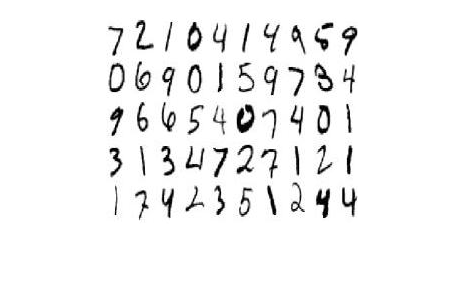

clear all
close all

%We load the classification model of our choice
load detectorModel
load detectorModelNN

%Open testing image and convert to gary scale
I=imread('digitrecognition1.jpg');
I=rgb2gray(I);
imshow(I)

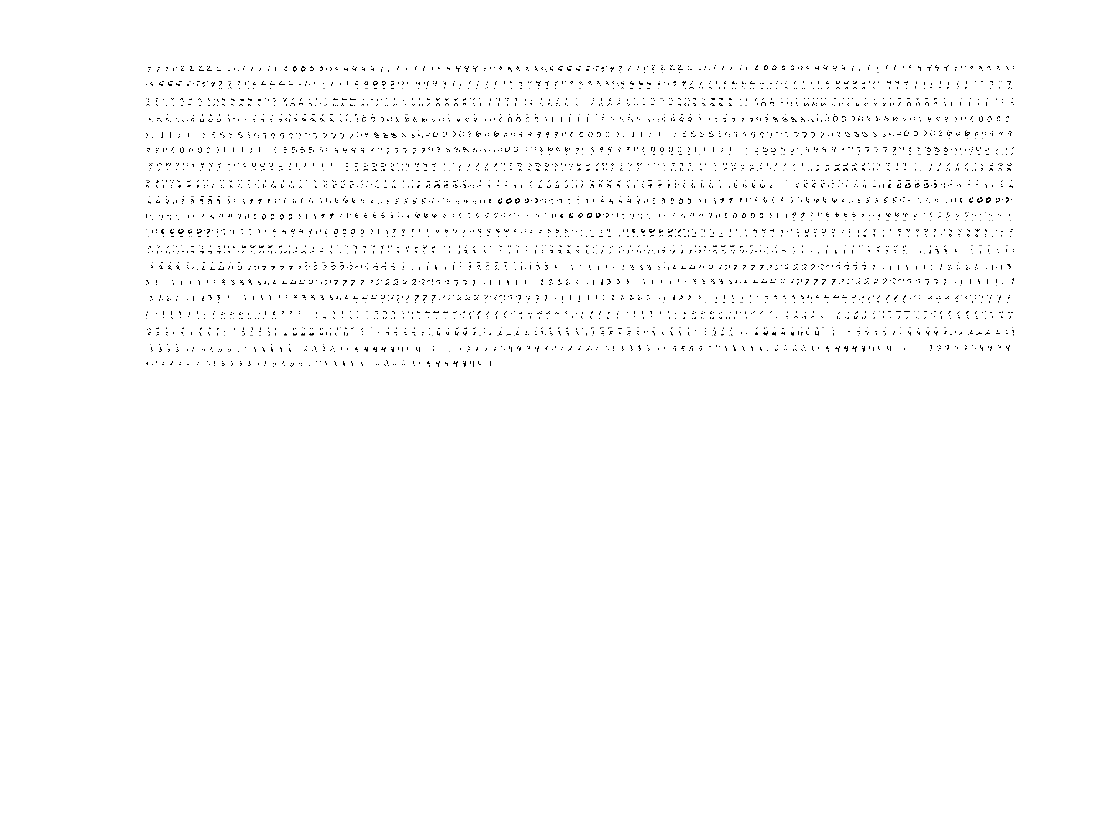


%For simplifying this task, we will assume we know that there are 5 rows of
%sigits, with 10 numbers each
numberRows=5;
numberColumns=10;

%Using previous infromation, we can calculate how tall and wide is each
%digit
samplingX=round(size(I,1)/numberRows);
samplingY=round(size(I,2)/numberColumns);

figure
digitCounter=0;

%Implementation of a simplified slidding window
% we will be accumulating all the predictions in this variable
predictedFullImage=[];
%for each digit within the image,

% VERSION 1 TASK 1-5
% for r=1:samplingX:size(I,1)
%     predictedRow=[];
%     for c= 1:samplingY:size(I,2)

% VERSION 2 TASK 6
county=0;
for r=1:5:size(I,1)
predictedRow=[];
county=county+1;
countx=0;
for c= 1:5:size(I,2)
countx=countx+1;
        
        if (c+samplingY-1 <= size(I,2)) && (r+samplingX-1 <= size(I,1))
            
            digitCounter =digitCounter+1;
            
            %we crop the digit
            digitIm = I(r:r+samplingX-1, c:c+samplingY-1);

            %All training examples were 28x28. To have any chance, we need to
            %resample them into a 28x28 imaGE
            digitIm = imresize(digitIm, [28 28]);
            
            % we convert it into doubles from 0 to 1 and invert them (rememebr that in the training set, the digitd were white on black background)
            digitIm = double(digitIm/255);           
            
            %We display teh individually segmented digits
            
            % VERSION 1
            % subplot(numberRows,numberColumns,digitCounter);

            % VERSION 2
            subplot(42, 85, digitCounter)
            imshow(digitIm, [0,1]);

            digitIm = preprocessDigit(digitIm);
            
            %we reshape the digit into a vector
            digitIm = reshape(digitIm, 1, []);
            
            % prediction = NNTesting(digitIm, modelNN);
            prediction =  SVMTesting(digitIm , modelSVM);
            
            predictedRow=[predictedRow prediction];
        end
    end
    
    predictedFullImage=[predictedFullImage; predictedRow];
end


predictedFullImage

predictedFullImage =      2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2    

## Evaluation

%Groundtruth
solutionTruth = [7 2 1 0 4 1 4 9 5 9;...
    0 6 9 0 1 5 9 7 3 4;...
    9 6 6 5 4 0 7 4 0 1;...
    3 1 3 4 7 2 7 1 2 1;...
    1 7 4 2 3 5 1 2 4 4];

comparison = (predictedFullImage==solutionTruth);

Error using  == 
Arrays have incompatible sizes for this operation.

Related documentation

Accuracy = sum(sum(comparison))/ (size(comparison,1)*size(comparison,2))